Scientific Programming - TCGA Ovarian Cancer dataset

02 - Clinical exploratory data analysis

clear;
clc;
close all;

load("results/cleaned_data.mat");

if ~exist("figures", "dir")
    mkdir("figures");
end

1. Cohort Overview

nPatients = height(clinical_dfs);
nEvents = sum(dfsEvent);
nCensored = sum(~dfsEvent);

fprintf("DFS cohort: %d patients\n", nPatients);

DFS cohort: 395 patients


fprintf("Recurrence/progression events: %d\n", nEvents);

Recurrence/progression events: 283


fprintf("Censored observations: %d\n", nCensored);

Censored observations: 112


2. Clinical variables distribution

stageTable = groupcounts(clinical_dfs, "TUMOR_STAGE_2009");
gradeTable = groupcounts(clinical_dfs, "GRADE");
residualTable = groupcounts(clinical_dfs, "TUMOR_RESIDUAL_DISEASE");

disp("Tumor stage distribution:")

Tumor stage distribution:


disp(stageTable)

    TUMOR_STAGE_2009    GroupCount    Percent
    ________________    __________    _______

        {'IIA' }             3        0.75949
        {'IIB' }             4         1.0127
        {'IIC' }            17         4.3038
        {'IIIA'}             6          1.519
        {'IIIB'}            17         4.3038
        {'IIIC'}           290         73.418
        {'IV'  }            57          14.43
        {'NA'  }             1        0.25316




disp("Grade distribution:")

Grade distribution:


disp(gradeTable)

    GRADE     GroupCount    Percent
    ______    __________    _______

    {'G2'}        47        11.899 
    {'G3'}       339        85.823 
    {'NA'}         9        2.2785 




disp("Residual disease distribution:")

Residual disease distribution:


disp(residualTable)

      TUMOR_RESIDUAL_DISEASE      GroupCount    Percent
    __________________________    __________    _______

    {'1-10 mm'               }       191        48.354 
    {'11-20 mm'              }        21        5.3165 
    {'>20mm'                 }        60         15.19 
    {'NA'                    }        43        10.886 
    {'No Macroscopic disease'}        80        20.253 



Candidate clinical variables for DFS analysis

- TUMOR_STAGE_2009

- GRADE

- TUMOR_RESIDUAL_DISEASE

- TMB_NONSYNONYMOUS

Treatment-response variables (PLATINUM_STATUS and PRIMARY_THERAPY_OUTCOME_SUCCESS) contain information after treatment.

DFS_STATUS and DFS_MONTHS define the outcome.

3. DFS event proportions by categorical clinical variables

event = patient had a documented recurrence/progression of the cancer during follow up.

It does not distinguish early recurrence from late recurrence. 

clinicalVariables = { ...
    "TUMOR_STAGE_2009", ...
    "GRADE", ...
    "TUMOR_RESIDUAL_DISEASE"};

for v = 1:numel(clinicalVariables)

    variableName = clinicalVariables{v};
    values = string(clinical_dfs.(variableName));

    % Remove missing values
    valid = values ~= "NA" & ~ismissing(values);

    values = categorical(values(valid));
    event = dfsEvent(valid);

    fprintf("\n%s\n", variableName);

    groups = categories(values);

    for i = 1:numel(groups)

        idx = values == groups{i};

        fprintf("%s: %d/%d events (%.1f%%)\n", ...
            groups{i}, ...
            sum(event(idx)), ...
            sum(idx), ...
            100*mean(event(idx)));
    end

    [~, chi2, p] = crosstab(values, event);

    fprintf("Chi-square = %.3f, p = %.4g\n", chi2, p);
end


TUMOR_STAGE_2009


IIA: 1/3 events (33.3%)
IIB: 2/4 events (50.0%)
IIC: 11/17 events (64.7%)
IIIA: 5/6 events (83.3%)
IIIB: 12/17 events (70.6%)
IIIC: 209/290 events (72.1%)
IV: 43/57 events (75.4%)


Chi-square = 4.346, p = 0.63



GRADE


G2: 39/47 events (83.0%)
G3: 239/339 events (70.5%)


Chi-square = 3.189, p = 0.07414



TUMOR_RESIDUAL_DISEASE


1-10 mm: 141/191 events (73.8%)
11-20 mm: 17/21 events (81.0%)
>20mm: 52/60 events (86.7%)
No Macroscopic disease: 47/80 events (58.8%)


Chi-square = 14.671, p = 0.002121


Event-rate plot for each variable:

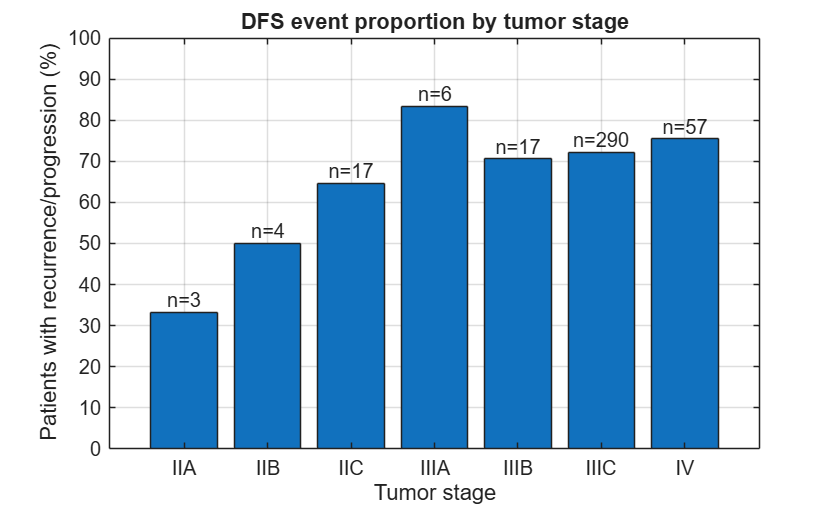

%% TUMOR STAGE

validStage = clinical_dfs.TUMOR_STAGE_2009 ~= "NA";

stage = categorical( ...
    clinical_dfs.TUMOR_STAGE_2009(validStage));

stage = reordercats(stage, { ...
    'IIA','IIB','IIC','IIIA','IIIB','IIIC','IV'});

event = dfsEvent(validStage);

stageGroups = categories(stage);

eventRate = zeros(numel(stageGroups),1);
nGroup = zeros(numel(stageGroups),1);

for i = 1:numel(stageGroups)

    idx = stage == stageGroups{i};

    nGroup(i) = sum(idx);
    eventRate(i) = 100 * mean(event(idx));

end

figure;

bar(categorical(stageGroups, stageGroups, ...
    'Ordinal', true), eventRate);

ylabel("Patients with recurrence/progression (%)");
xlabel("Tumor stage");
title("DFS event proportion by tumor stage");

ylim([0 100]);
grid on;

hold on;

for i = 1:numel(stageGroups)

    text(i, eventRate(i) + 3, ...
        sprintf("n=%d", nGroup(i)), ...
        "HorizontalAlignment","center");

end

hold off;

saveas(gcf, "figures/DFSproportion_tumorstage.png");

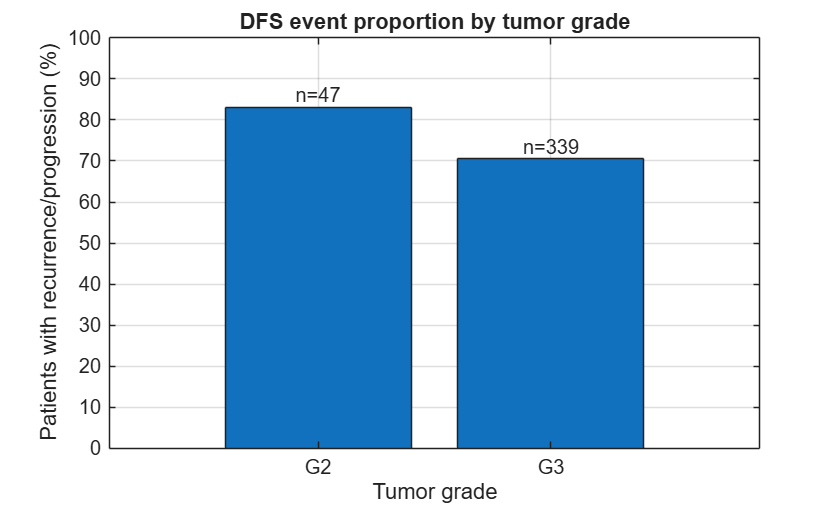


%% GRADE

validGrade = clinical_dfs.GRADE ~= "NA";

grade = categorical( ...
    clinical_dfs.GRADE(validGrade));

grade = reordercats(grade, {'G2','G3'});

event = dfsEvent(validGrade);

gradeGroups = categories(grade);

eventRate = zeros(numel(gradeGroups),1);
nGroup = zeros(numel(gradeGroups),1);

for i = 1:numel(gradeGroups)

    idx = grade == gradeGroups{i};

    nGroup(i) = sum(idx);
    eventRate(i) = 100 * mean(event(idx));

end

figure;

bar(categorical(gradeGroups, gradeGroups, ...
    'Ordinal', true), eventRate);

ylabel("Patients with recurrence/progression (%)");
xlabel("Tumor grade");
title("DFS event proportion by tumor grade");

ylim([0 100]);
grid on;

hold on;

for i = 1:numel(gradeGroups)

    text(i, eventRate(i) + 3, ...
        sprintf("n=%d", nGroup(i)), ...
        "HorizontalAlignment","center");

end

hold off;

saveas(gcf, "figures/DFSproportion_tumorgrade.png");

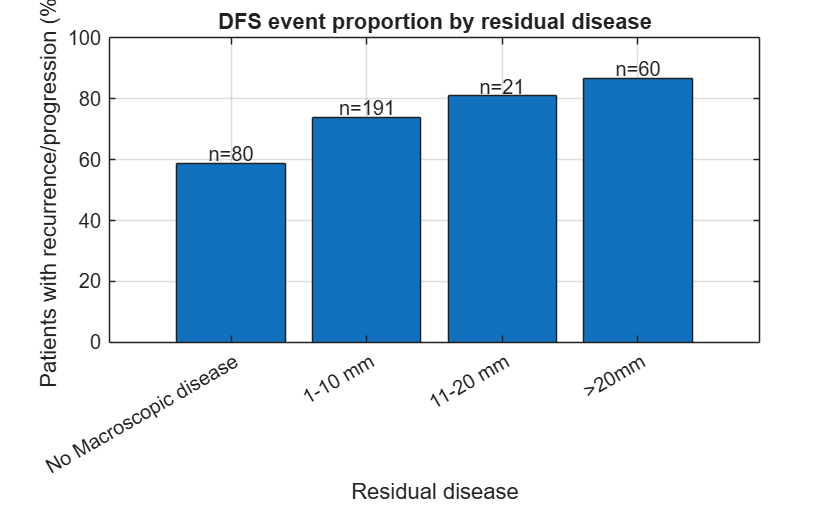


%% RESIDUAL DISEASE

validResidual = clinical_dfs.TUMOR_RESIDUAL_DISEASE ~= "NA";

residual = categorical( ...
    clinical_dfs.TUMOR_RESIDUAL_DISEASE(validResidual));

residual = reordercats(residual, { ...
    'No Macroscopic disease', ...
    '1-10 mm', ...
    '11-20 mm', ...
    '>20mm'});

event = dfsEvent(validResidual);

residualGroups = categories(residual);

eventRate = zeros(numel(residualGroups),1);
nGroup = zeros(numel(residualGroups),1);

for i = 1:numel(residualGroups)

    idx = residual == residualGroups{i};

    nGroup(i) = sum(idx);
    eventRate(i) = 100 * mean(event(idx));

end

figure;

bar(categorical(residualGroups, residualGroups, ...
    'Ordinal', true), eventRate);

ylabel("Patients with recurrence/progression (%)");
xlabel("Residual disease");
title("DFS event proportion by residual disease");

ylim([0 100]);
grid on;

hold on;

for i = 1:numel(residualGroups)

    text(i, eventRate(i) + 3, ...
        sprintf("n=%d", nGroup(i)), ...
        "HorizontalAlignment","center");

end

hold off;

saveas(gcf, "figures/DFSproportion_residualdisease.png");

Tumor stage: not significantly associated with DFS event status, altough some early-stage groups showed different event proportions. The groups contain very few patients so the results should not be overinterpreted.

Tumor grade: no statistically significant association with DFS event status.

Residual disease: clear relationship with recurrence/progression. The even proportion increased from 58.8% in patients with no macroscopic disease to 86.7% in patients with residual disease >20 mm and the association was statistically significant. 

4. Kaplan-Meier survival analysis for clinical variables

- Do patients remain disease-free for different lenghts of time?

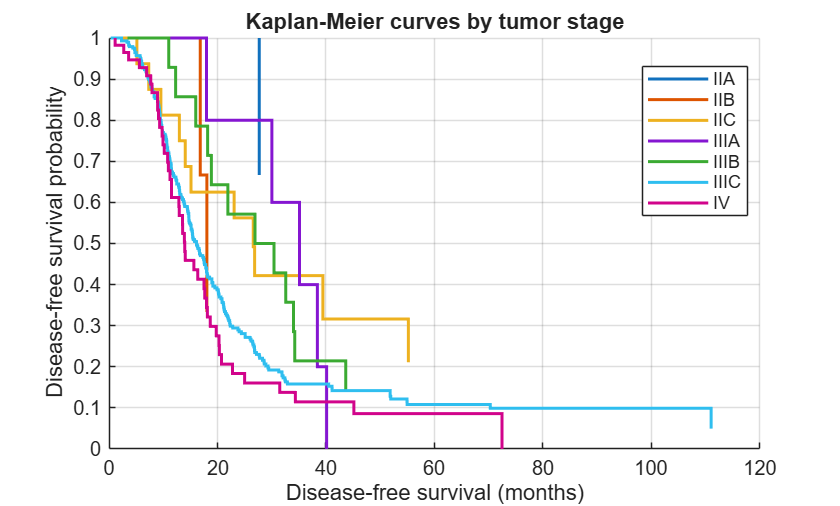

%% TUMOR STAGE
validStage = clinical_dfs.TUMOR_STAGE_2009 ~= "NA";

time = clinical_dfs.DFS_MONTHS(validStage);
event = dfsEvent(validStage);

stage = categorical( ...
    clinical_dfs.TUMOR_STAGE_2009(validStage));

stage = reordercats(stage, { ...
    'IIA','IIB','IIC','IIIA','IIIB','IIIC','IV'});

stageGroups = categories(stage);

figure;
hold on;

for i = 1:numel(stageGroups)

    idx = stage == stageGroups{i};

    censored = ~event(idx);

    [f,x] = ecdf( ...
        time(idx), ...
        "Censoring", censored, ...
        "Function", "survivor");

    stairs(x, f, "LineWidth", 1.5);

end

xlabel("Disease-free survival (months)");
ylabel("Disease-free survival probability");
title("Kaplan-Meier curves by tumor stage");

legend(stageGroups, "Location", "best");
grid on;
hold off;

saveas(gcf, "figures/kaplanmeier_tumorstage.png");

Tumor stage: substantial overlap between groups, no clear separation in disease-free survival is visible. Early stage curbes are unstable due to these groups having only a few patients.

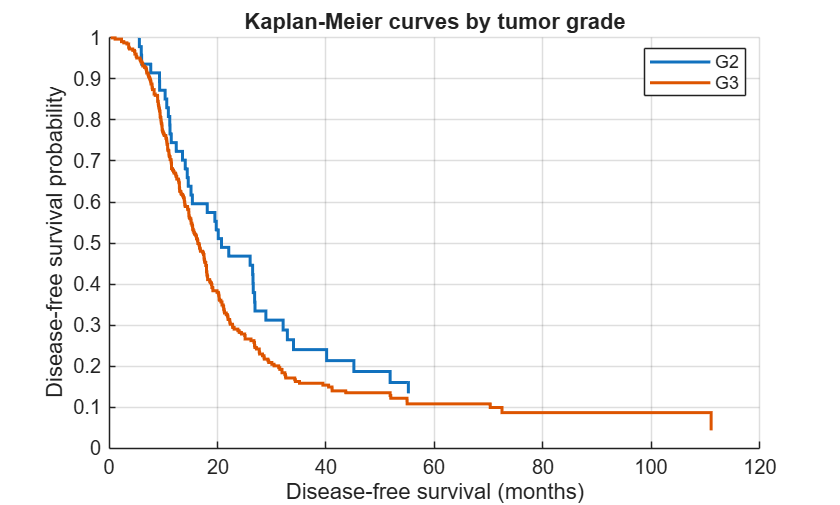

%% TUMOR GRADE
validGrade = clinical_dfs.GRADE ~= "NA";

time = clinical_dfs.DFS_MONTHS(validGrade);
event = dfsEvent(validGrade);

grade = categorical( ...
    clinical_dfs.GRADE(validGrade));

grade = reordercats(grade, {'G2','G3'});

gradeGroups = categories(grade);

figure;
hold on;

for i = 1:numel(gradeGroups)

    idx = grade == gradeGroups{i};

    censored = ~event(idx);

    [f,x] = ecdf( ...
        time(idx), ...
        "Censoring", censored, ...
        "Function", "survivor");

    stairs(x, f, "LineWidth", 1.5);

end

xlabel("Disease-free survival (months)");
ylabel("Disease-free survival probability");
title("Kaplan-Meier curves by tumor grade");

legend(gradeGroups, "Location", "best");
grid on;
hold off;

saveas(gcf, "figures/kaplanmeier_tumorgrade.png");

Tumor grade: suggest better disease-free survival for G2 compared to G3, altought there is still overlap between the curves. Formal survival rest is required for further interpretation. 

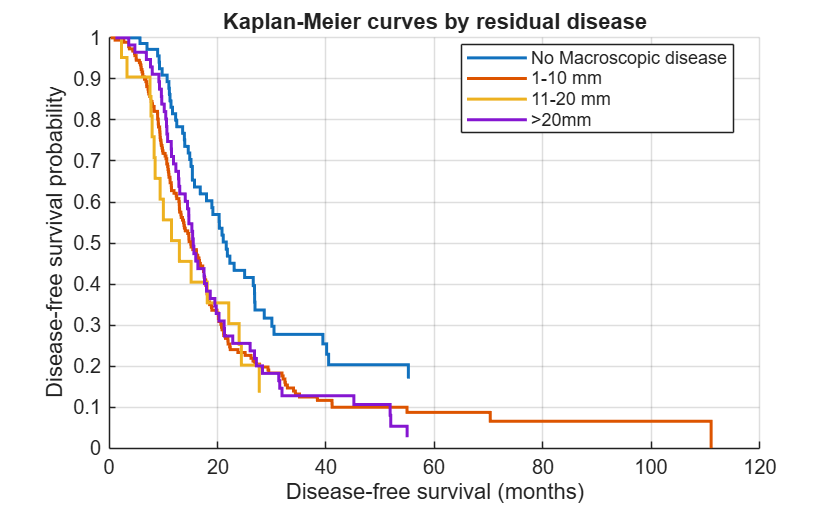

%% RESIDUAL DISEASE
validResidual = clinical_dfs.TUMOR_RESIDUAL_DISEASE ~= "NA";

time = clinical_dfs.DFS_MONTHS(validResidual);
event = dfsEvent(validResidual);

residual = categorical( ...
    clinical_dfs.TUMOR_RESIDUAL_DISEASE(validResidual));

residual = reordercats(residual, { ...
    'No Macroscopic disease', ...
    '1-10 mm', ...
    '11-20 mm', ...
    '>20mm'});

residualGroups = categories(residual);

figure;
hold on;

for i = 1:numel(residualGroups)

    idx = residual == residualGroups{i};

    censored = ~event(idx);

    [f,x] = ecdf( ...
        time(idx), ...
        "Censoring", censored, ...
        "Function", "survivor");

    stairs(x, f, "LineWidth", 1.5);

end

xlabel("Disease-free survival (months)");
ylabel("Disease-free survival probability");
title("Kaplan-Meier curves by residual disease");

legend(residualGroups, "Location", "best");
grid on;
hold off;

saveas(gcf, "figures/kaplanmeier_residualdisease.png");

Residual disease: patients with no macroscopic residual disease show the highest disease-free survival probability over time. The residual-disease groups show poorer DFS and overlap with each other. Formal survival comparison is required to test if the curves differ significantly. 

5. Log-rank test by tumor stage

note: function at the bottom of the script

validStage = clinical_dfs.TUMOR_STAGE_2009 ~= "NA";

stageTime = clinical_dfs.DFS_MONTHS(validStage);
stageEvent = dfsEvent(validStage);

stage = categorical( ...
    clinical_dfs.TUMOR_STAGE_2009(validStage));

stage = reordercats(stage, { ...
    'IIA','IIB','IIC','IIIA','IIIB','IIIC','IV'});

[chi2_stage, p_stage, df_stage] = ...
    logrankTest(stageTime, stageEvent, stage);

fprintf("\nLog-rank test - Tumor stage\n");


Log-rank test - Tumor stage


fprintf("Chi-square = %.3f\n", chi2_stage);

Chi-square = 13.411


fprintf("Degrees of freedom = %d\n", df_stage);

Degrees of freedom = 6


fprintf("p-value = %.4g\n", p_stage);

p-value = 0.03695


The log-rank test showed significant difference in DFS across tumor stage groups, suggesting that survival overtime differs by stage. But interpretation should remain cautious as several groups contain very few patients. 

Log-rank test by tumor grade

validStage = clinical_dfs.GRADE ~= "NA";

stageTime = clinical_dfs.DFS_MONTHS(validStage);
stageEvent = dfsEvent(validStage);

stage = categorical( ...
    clinical_dfs.GRADE(validStage));

[chi2_stage, p_stage, df_stage] = ...
    logrankTest(stageTime, stageEvent, stage);

fprintf("\nLog-rank test - Tumor grade\n");


Log-rank test - Tumor grade


fprintf("Chi-square = %.3f\n", chi2_stage);

Chi-square = 2.641


fprintf("Degrees of freedom = %d\n", df_stage);

Degrees of freedom = 1


fprintf("p-value = %.4g\n", p_stage);

p-value = 0.1041


No significant difference in DFS between tumor grades G2 an G3.

Log-rank test by residual disease

validStage = clinical_dfs.TUMOR_RESIDUAL_DISEASE ~= "NA";

stageTime = clinical_dfs.DFS_MONTHS(validStage);
stageEvent = dfsEvent(validStage);

stage = categorical( ...
    clinical_dfs.TUMOR_RESIDUAL_DISEASE(validStage));

[chi2_stage, p_stage, df_stage] = ...
    logrankTest(stageTime, stageEvent, stage);

fprintf("\nLog-rank test - Tumor residual disease\n");


Log-rank test - Tumor residual disease


fprintf("Chi-square = %.3f\n", chi2_stage);

Chi-square = 10.805


fprintf("Degrees of freedom = %d\n", df_stage);

Degrees of freedom = 3


fprintf("p-value = %.4g\n", p_stage);

p-value = 0.01283


The test showed a significant difference in DFS across residual-disease groups. Patients with no macroscopic residual disease showed the best disease-free survival over time. 

function [chi2, p, df] = logrankTest(time, event, group)

    time = time(:);
    event = logical(event(:));
    group = categorical(group(:));

    groupNames = categories(group);
    k = numel(groupNames);

    O = zeros(k,1);   % observed events
    E = zeros(k,1);   % expected events
    V = zeros(k,k);   % variance-covariance matrix

    eventTimes = unique(time(event));

    for t = eventTimes'

        atRisk = time >= t;
        eventsNow = event & time == t;

        Y = sum(atRisk);
        d = sum(eventsNow);

        Yg = zeros(k,1);
        dg = zeros(k,1);

        for g = 1:k
            inGroup = group == groupNames{g};

            Yg(g) = sum(atRisk & inGroup);
            dg(g) = sum(eventsNow & inGroup);
        end

        O = O + dg;
        E = E + d * (Yg / Y);

        if Y > 1
            pRisk = Yg / Y;

            V = V + ...
                d * (Y - d) / (Y - 1) * ...
                (diag(pRisk) - pRisk * pRisk');
        end
    end

    difference = O - E;

    chi2 = difference' * pinv(V) * difference;
    df = k - 1;
    p = 1 - chi2cdf(chi2, df);

end